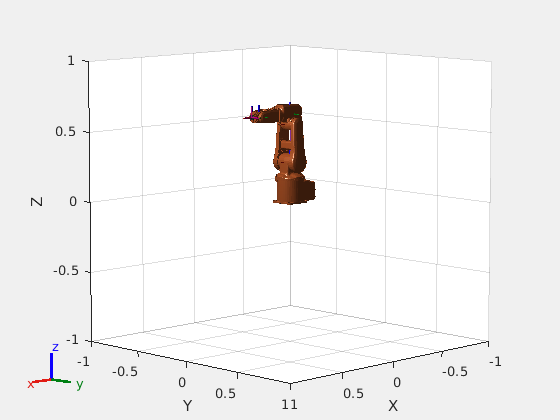

robot = loadrobot("abbIrb120");
show(robot);

disp(robot);

  rigidBodyTree with properties:

     NumBodies: 8
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'link_1'  'link_2'  'link_3'  'link_4'  'link_5'  'link_6'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'



config = robot.homeConfiguration;
jvals = [1.056859 0.84090817 0.24093068 0.01547204 -0.6826017 0.00185656];
config(1).JointPosition = jvals(1);
config(2).JointPosition = jvals(2);
config(3).JointPosition = jvals(3);
config(4).JointPosition = jvals(4);
config(5).JointPosition = jvals(5);
config(6).JointPosition = jvals(6);

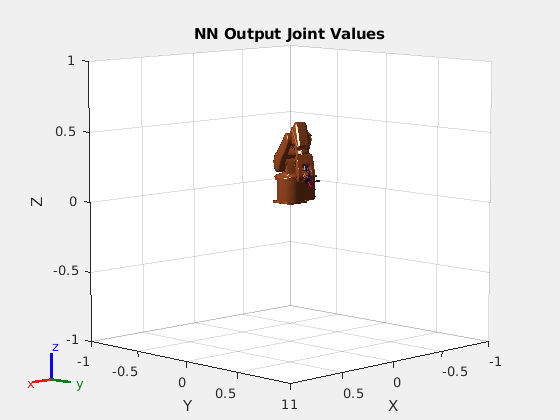

show(robot,config);
title('NN Output Joint Values');

newpose = getTransform(robot,config,"link_6");
disp('POSE by joint angles for neural network:')

POSE by joint angles for neural network:


disp(newpose(1,4));

    0.2323



disp(newpose(2,4));

    0.4100



disp(newpose(3,4));

    0.2083



### ACTUAL KINEMATICS

pos = [0.2185 0.40765 0.19339];
posvec = trvec2tform(pos);
disp(posvec);

    1.0000         0         0    0.2185
         0    1.0000         0    0.4077
         0         0    1.0000    0.1934
         0         0         0    1.0000




ik = inverseKinematics("RigidBodyTree",robot);
weights = [0 0 0 1 1 1];
initialguess = homeConfiguration(robot);

[configSoln,solnInfo] = ik("link_6",posvec,weights,initialguess);
disp(solnInfo);

           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7315e-09
             ExitFlag: 1
               Status: 'success'



for i =1:6
    disp(configSoln(i).JointPosition);
end

    1.0788

    0.8402

    0.1622

    0.0092

   -0.0184

     0



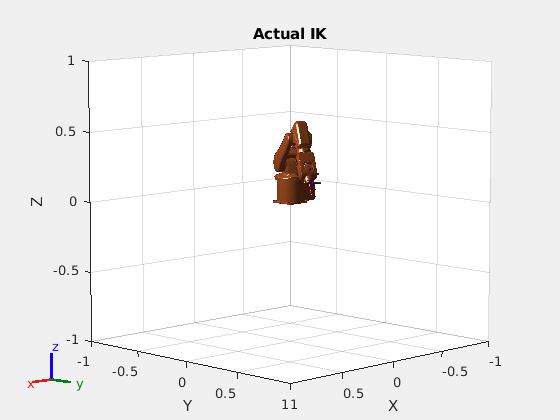

pose = getTransform(robot,configSoln,"link_6");
%disp(pose(2,4));
%disp(pose(3,4));
show(robot,configSoln);
title('Actual IK');